# Stationary Kalman Filter and Drifting Disturbance Estimation

**Sachin C. Patwardhan*, Anjali P. Deshpande and Sharad Bhartiya* **

(*) Dept. of Chemical Engineering,

 Indian Institute of Technology Bombay, Mumbai 400076 India  

## Introduction

We have seen [earlier](matlab:open('./L03_KalmanFilter.mlx')), the Sequential State Estimation using Kalman Filter. In the demonstration we have observed that the filter gain becomes constant after initial few time samples. When a system is operated over a long time interval or operated continuously, using the sequential time varying Kalman gain computation becomes redundant in most cases as Riccati equations reach the stationary point.  Thus, we can compute the stationary or steady state Kalman Gain and use it as a constant filter gain matrix in such applications . This is qualitatively similar to the use of the steady state controller gain matrix, $G_{\infty }$, in LQOC. This saves the computation time without without significant loss in the estimator performance. Some important aspects are

- This reduces computational cost significantly — ideal for real-time or embedded systems.

- Accuracy remains high if the system is linear and noise statistics remain unchanged 

So far we have assumed that the unmeasured disturbance signal d(k) behaves like a zero mean white noise. While this simplistic assumption helps in developing Kalman filtering theory, the mean of unmeasured disturbances drifts in practical applications. Thus, we study how state estimators design can be modified for estimating the drifting mean of the unmeasured disturbance using a random walk model augmented with the original state space model. 

Learning objectives of this lesson are 

- Develop stationary Kalman Predictor and Filter

- Establish the nominal stability of the Kalman predictor and filter error dynamics

- Develop drifting disturbance estimators using random walk model  

## Stationary Kalman Filter and Predictor 

### Stationary Kalman Predictor 

Recall that the covariance prediction error for Kalman predictor is updated as follows 

$P\left(k+1|k\right)=\Phi P\left(k|k-1\right)\Phi^T -L_p \left(k\right)\textrm{CP}\left(k|k-1\right)\Phi^T +Q$  ------(1)

$L_p \left(k\right)=\Phi P\left(k|k-1\right){C^T \left\lbrack \textrm{CP}\left(k|k-1\right)C^T +R\right\rbrack }^{-1}$-------(2)

Note that these are matrix difference equations in $P\left(\ldotp \right)$ forward in time and we move from $P\left(k-1|k-1\right)$ to $P\left(k|k\right)$ as k increases.  As $k\to \infty$, under some weak conditions, the optimal estimator will be time invariant the predicted and updated covariance reach a steady value $P\left(k|k-1\right)\to P_{\infty }$

$P_{\infty } =\Phi P_{\infty } \Phi^T -L_{p,\infty } CP_{\infty } \Phi^T +Q$  ------(3)

$L_{p,\infty } =\Phi P_{\infty } {C^T \left\lbrack CP_{\infty } C^T +R\right\rbrack }^{-1}$  ------(4)

. The optimal kalman gain also reaches a steady value, $L_p \left(k\right)\to L_{p,\infty }$. The resulting recursive prediction estimator can be written as

$\left.e\left(k\right)=y\left(k\right)-\textrm{Cx}̂\left(k\right|k-1\right)$      -----(5)

$x̂\left(k+1\right|k\right)=\Phi x̂\left(k\left|k-1\right)+\Gamma u\left(k\right)+L_{p,\infty } e\left(k\right)$  ------(6)

This is referred to as the **Stationary Kalman predictor.** The following results specify conditions for convergence to the stationary solution. The **Kalman Predictor** estimates the **future state** using only past measurements — **not the current measurement**.

**Theorem**

Assume pair $\left(\Phi ,\sqrt{Q}\right)$ is stabilizable and the pair $\left(\Phi ,C\right)$ is detectable Then the solution of the Riccati equation $P\left(k|k-1\right)\to P_{\infty } >0$ where $P_{\infty }$ denotes solution of the Algebraic Riccati Equations (3) and (4). 

### Stationary Kalman Filter 

As $k\to \infty$, under weak conditions the Kalman filter gain becomes time invariant the as the Riccati equations reach equilibrium, i.e. $P\left(k|k-1\right)\to P_{\infty } \;,\;\;P\left(k|k\right)\to {\tilde{P} }_{\infty } \;\textrm{and}\;L_c \left(k\right)\to L_{c,\infty }$  where these quantities are related through Algebraic Riccati equations 

$P_{\infty } =\Phi \tilde{P_{\infty } } \Phi^T +Q$  ------(7)

$\tilde{P_{\infty } } =\left\lbrack I-{\mathrm{L}}_{c,\infty } C\right\rbrack P_{\infty }$  ------(8)

where the optimal stationary gain is computed as 

$L_{c,\infty } =P_{\infty } {C^T \left\lbrack CP_{\infty } C^T +R\right\rbrack }^{-1}$ ------(9)

The computation steps in the resulting stationary Kalman filter are as follows 

$\hat{x} \left(k|k-1\right)=\Phi \hat{x} \left(k-1|k-1\right)+\Gamma u\left(k-1\right)$   ------(10)

$e\left(k\right)=y\left(k\right)-C\hat{x} \left(k|k-1\right)$   -------(11)

$\hat{x} \left(k|k\right)=\hat{x} \left(k|k-1\right)+L_{c,\infty } e\left(k\right)$   ---------(12)

The **Kalman Filter** provides the **best estimate of the current state** using:

- Prediction (Time Update)

- Correction using the current measurement

## Nominal Stability of Stationary Kalman Filter

In this section, we establish the nominal stability of stationary Kalman predictor and Kalman filter.  It is assumed that** t**he Algebraic Riccati Equation (3) has a positive definite solution, $P_{\infty } >0$. The  stationary Kalman predictor can be written as an innovation form of state space model  

$x̂\left(k+1\right|k\right)=\Phi x̂\left(k\left|k-1\right)+\Gamma u\left(k\right)+L_{p,\infty } e\left(k\right)$  ------(13)

$\left.y\left(k\right)=\textrm{Cx}̂\left(k\right|k-1\right)+e\left(k\right)$  ------(14)

We use an alternate expression for ARE (3), which stated as follows 

 $P_{\infty } =\left(\Phi -L_{p,\infty } C\right)P_{\infty } {\left(\Phi -L_{p,\infty } C\right)}^T +Q+L_{p,\infty } R{\left(L_{p,\infty } \right)}^T$  ------(15)

Consider steady state Kalman Predictor implemented on a linear noise free system that evolves as follows 

$\begin{array}{l}
x\left(\textrm{𝑘}+1\right)=\Phi x\left(\textrm{𝑘}\right)+\Gamma u\left(\textrm{𝑘}\right)\\
y\left(\textrm{𝑘}\right)=Cx\left(\textrm{𝑘}\right)
\end{array}$ ------(16)

The predicted estimation error dynamics are given by 

$\varepsilon \left(\textrm{𝑘}+1\right|\textrm{𝑘}\right)=\left(\Phi -L_{p,\infty } C\right)\;\varepsilon \left(\textrm{𝑘}\left|\textrm{𝑘}-1\right)$ ------(17)

where $\left.\varepsilon \left(\textrm{𝑘}\right|\textrm{𝑘}-1\right)=x\left(k\right)-\hat{x} \left(k|k-1\right)$.  Now Consider a hypothetical discrete time system given by

$\xi \left(k+1\right)={\left(\Phi -L_{p,\infty } C\right)}^T \xi \left(k\right)$ ------(18)

Consider candidate Lyapunov function

$V\left\lbrack \xi \left(k\right)\right\rbrack ={\xi \left(k\right)}^T P_{\infty } \xi \left(k\right)$ ------(19)

$\begin{array}{l}
\textrm{𝑉}\left\lbrack \textrm{𝛏}\left(k+1\right)\right\rbrack ={\xi \left(k+1\right)}^T P_{\infty } \xi \left(k+1\right)\\
\textrm{𝑉}\left\lbrack \textrm{𝛏}\left(k+1\right)\right\rbrack ={\xi \left(k\right)}^T {\left\lbrack {\left(\Phi -L_{p,\infty } C\right)}^T \right\rbrack }^T P_{\infty } {\left(\Phi -L_{p,\infty } C\right)}^T \textrm{𝛏}\left(k\right)
\end{array}$ ------(20)

$\Delta \textrm{𝑉}\left\lbrack \textrm{𝛏}\left(k\right)\right\rbrack ={\textrm{𝛏}\left(\textrm{𝑘}\right)}^T \left(\left(\Phi -L_{p,\infty } C\right)\right)P_{\infty } {\left.\left(\Phi -L_{p,\infty } \right)C\right)}^T -P_{\infty } \right)\textrm{𝛏}\left(k\right)=-{\textrm{𝛏}\left(k\right)}^T \left(Q+L_{p,\infty } R{\left(L_{p,\infty } \right)}^T \textrm{𝛏}\left(k\right)$ ------(21)

Note: $\left(Q+L_{p,\infty } R{\left(L_{p,\infty } \right)}^T \right.$ is  positive definite matrix and it follows that 

$\Delta \textrm{𝑉}\left\lbrack \textrm{𝛏}\left(k\right)\right\rbrack ={\textrm{𝛏}\left(\textrm{𝑘}\right)}^T \left(\left(\Phi -L_{p,\infty } C\right)P_{\infty } {\left(\Phi -L_{p,\infty } \textrm{𝐂}\right)}^T -P_{\infty } \right)\textrm{𝛏}\left(k\right)<0$ when  $\xi \left(k\right)\not= \bar{0}$

Thus,  $V\left\lbrack \xi \left(k\right)\right\rbrack$ is a Lyapunov function for the hypothetical discrete time system and all eigenvalues of $\Phi^T -{\left(L_{\infty }^* C\right)}^T$are strictly inside the unit circle. Since eigenvalues of $\Phi^T -{\left(L_{\infty }^* C\right)}^T$ are identical to eigenvalues of $\Phi -L_{p,\infty } \textrm{𝐂}$, the estimation error dynamics is asymptotically stable.

    Since the spectral radius $\rho \left(\Phi -L_{p,\infty } \textrm{𝐂}\right)<1$ the prediction error dynamics

 $\varepsilon \left(k+1\right|k\right)=\left(\Phi -L_{p,\infty } \textrm{𝐂}\right)\varepsilon \left(k\left|k-1\right)$ ------(22)

is asymptotically stable and  $\left\|\varepsilon \left(k\right|k-1\right)\left\|\to 0\right.$  as $k\to \infty$ 

    Now, the steady state Kalman filter update step is carried out using equation (14),  which implies 

 $\left.\varepsilon \left(k\right|k\right)=\left(I-L_{p,\infty } C\right)\varepsilon \left(k\left|k-1\right)\Rightarrow \left\|\varepsilon \left(k\right|k\right)\left\|\le \right\|\left(I-L_{p,\infty } C\right)\left\|\right\|\varepsilon \left(k\right|k-1\right)\|$   ------(23)

Since $\left\|\varepsilon \left(k\right|k-1\right)\left\|\to 0\right.$ as  $k\to \infty$ it follows that$\left\|\varepsilon \left(k\right|k\right)\left\|\to 0\right.$ as  $k\to \infty$  Thus, estimation error dynamics of steady state Kalman filter is also asymptotically stable.  

### Quadruple Tank Simulation 

Let us design and implement a stationary Kalman filter and Kalman predictor for the quadruple tank system. 

clear all 

**Task 1: **On selecting the operating point, corresponding steady state linear discrete model and parameters will be loaded in the workspace. Set it to Minimum Phase 

operating_pt=1;

% Load quadruple tank parameters and steady state The following file loads QTank data structure 
if operating_pt==1
load QTank_MinPhase_Model
else
 load QTank_NonMinPhase_Model 
end

phy= QTank.phy ;  
gam = QTank.gama_u ;
gam_d = QTank.gama_d ; 
C_mat = QTank.C_mat ; 

[n_st,n_ip] = size(gam);
[n_op, nx] = size(C_mat) ;
[nx, n_d] = size(gam_d)  ; 
samp_T = 4 ;  
QT_sys = ss(phy, [gam gam_d], C_mat, zeros(n_op,n_ip+n_d), QTank.samp_T ) ;

**Design Kalman predictor** 

We have set the state noise variance and measurement noise variance to 0.01 each.

% Stationary Kalman filter predictor design 
v_sigma = 0.1 ;
R_mat = v_sigma^2*eye(n_op) ;
d_sigma = 0.1 ;
Q_mat = d_sigma^2*eye(n_d) ;

 % Kalman filter or current state estimator design
 [KEST,Lc_inf,P_inf] = kalman(QT_sys, Q_mat, R_mat, 0,"current")  ;
 disp('Kalman Filter Gain')

Kalman Filter Gain


 Lc_inf 

Lc_inf =     0.0081    0.0117
    0.0120    0.0190
    0.0030    0.0034
    0.0060    0.0074


 disp('Kalman Predictor Gain')

Lp_inf =     0.0080    0.0115
    0.0122    0.0190
    0.0025    0.0029
    0.0054    0.0066


These are used in implementing the Kalman Filter and Kalman Predictor. 

 Lp_inf = phy * Lc_inf 

rho_obs = 0.9495

 rho_obs = max(abs(eig(phy - Lp_inf * C_mat )))

rho_phy = 0.9595

rho_phy = max(abs(eig(phy))) 

Simulate the observer dynamics. N is set to 150

N = 150 ; % Simulation run time 

% Generate Input sequence 
uk1 = idinput(N,'rgs', [0,0.1]);
uk2 = idinput(N,'rgs', [0,0.1]);
uk = [ uk1' ; uk2'] ;

% Initialize matrices for saving 
xk = zeros(n_st, N) ;
yk = zeros(n_op,N) ;
xk(:,1) = [ 4 -4 3 -3]';
yk(:,1) = C_mat * xk(:,1) ;

xkhat = zeros(n_st, N) ;
xkkhat = zeros(n_st, N) ;
ykhat = zeros(n_op,N) ;
ek = zeros(n_op,N) ;

% Generate state and measurement noise sequence 
v_sigma = 0.1 ;
R_mat = v_sigma^2*eye(n_op) ;
d_sigma = 0.15 ;
Q_mat = d_sigma^2*eye(n_d) ;
vk = mvnrnd(zeros(n_op,1), R_mat, N) ;  % Generate measurement noise
vk = vk';
dk = mvnrnd(zeros(n_d,1), Q_mat , N) ;  % Generate state noise
dk = dk';

**Task 2: **Set the NO_Noise flag to **Switch OFF Noise** for simulating system under noise free conditions

NO_Noise =  0; % Set this flag for simulating system under noise free conditions 
if (NO_Noise)
    vk = 0 * vk ;  dk = 0 * dk ;  % Set state and measurement noise to zero 
end 

**Task 3: **Select the estimation method for simulating system with Kalman Filter, or Kalman Predictor. Set it to Kalman Predictor first. Plant dynamics from k to k+1 is simulated using linear discrete time model. 

est_method = 2;  % Select type of estimator 

kT = zeros(N,1) ;
for k = 1 : N-1
    kT(k+1) = (k-1) ;

    % Simulate observer dynamics from k to k+1
    
    if (est_method == 1 )
        % Stationary Kalman predictor 
         ykhat(:,k) = C_mat * xkhat(:,k) ; 
         ek(:,k) = yk(:,k) - ykhat(:,k) ;
        xkhat(:,k+1)= phy * xkhat(:,k) + gam * uk(:,k) + Lp_inf * ek(:,k) ;
    else
        % Current state observer
        if (k>=2)
            xkhat(:,k) = phy * xkkhat(:,k-1) + gam * uk(:,k-1) ;
            ykhat(:,k) = C_mat * xkhat(:,k) ; 
            ek(:,k) = yk(:,k) - ykhat(:,k) ; 
            xkkhat(:,k)= xkhat(:,k) + Lc_inf * ek(:,k) ;
        end
    end

    ykhat(:,k+1) = C_mat * xkhat(:,k+1) ; 

    % Simulate plant dynamics from k to k+1 
    xk(:,k+1)= phy * xk(:,k) + gam * uk(:,k) + gam_d * dk(:,k) ;
    yk(:,k+1) = C_mat * xk(:,k+1) + vk(:,k+1) ; 
end
ek(:,N) = ek(:,N-1) ; 

if ( est_method == 1 )
    est_err = xkhat - xk ;  % State estimation error
else
    k = N ; 
    xkhat(:,k) = phy * xkkhat(:,k-1) + gam * uk(:,k-1) ;
    ykhat(:,k) = C_mat * xkhat(:,k) ;
    ek(:,k) = yk(:,k) - ykhat(:,k) ;
    xkkhat(:,k)= xkhat(:,k) + Lc_inf * ek(:,k) ;
    est_err = xkkhat - xk ;  % State estimation error
end

**Display Simulation Results**

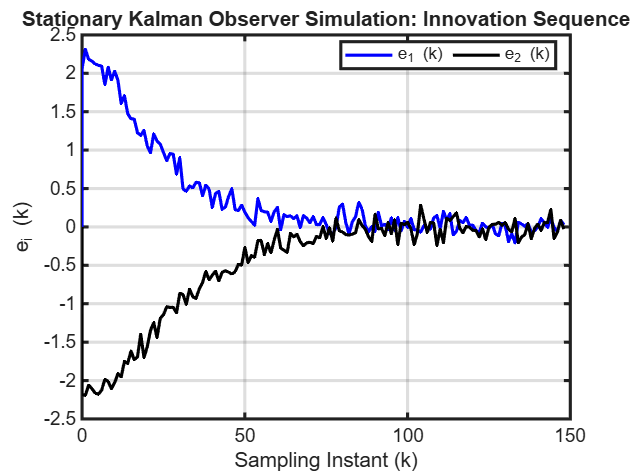

Set_Graphics_Parameters ;

figure(1), plot(kT, ek(1,:), 'b', kT, ek(2,:), 'k'), grid
xlabel('Sampling Instant (k)'), ylabel('e_i (k)')
legend('e_1 (k)', 'e_2 (k)', 'Orientation','horizontal','Location','Best') 
title('Stationary Kalman Observer Simulation: Innovation Sequence')

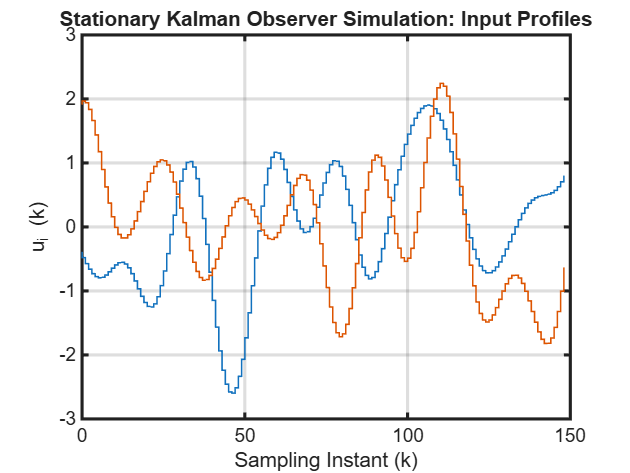

figure(2), stairs(kT, uk', 'LineWidth',1), grid
xlabel('Sampling Instant (k)'), ylabel('u_i (k)'), 
title('Stationary Kalman Observer Simulation: Input Profiles')

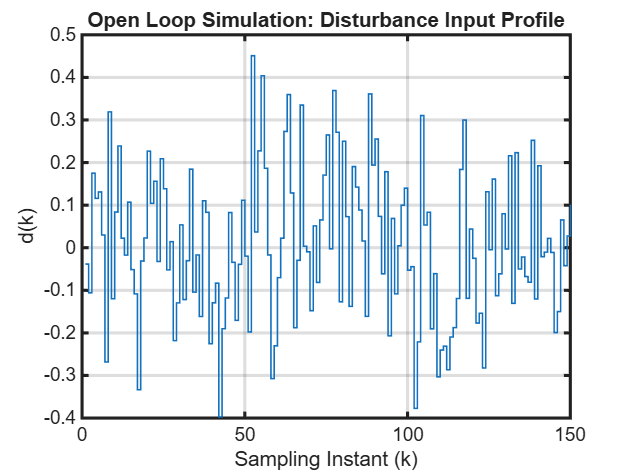

figure(3), stairs(dk, 'LineWidth',1), grid
xlabel('Sampling Instant (k)'), ylabel('d(k)'), title('Open Loop Simulation: Disturbance Input Profile')

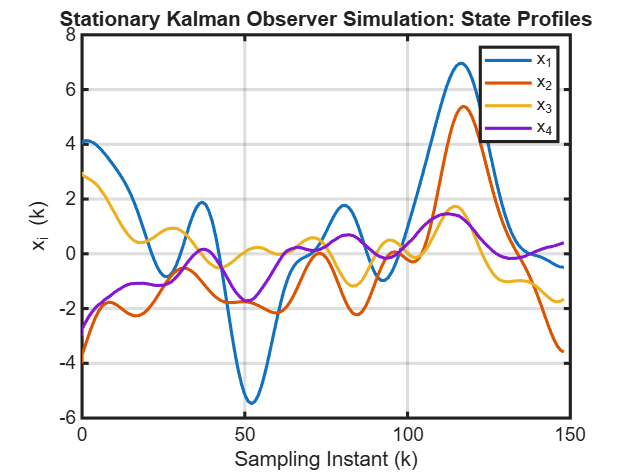

figure(4), plot(kT, xk(1,:), kT, xk(2,:), kT, xk(3,:), kT, xk(4,:)), grid
xlabel('Sampling Instant (k)'), ylabel('x_i (k)')
legend('x_1', 'x_2', 'x_3', 'x_4'), 
title('Stationary Kalman Observer Simulation: State Profiles')

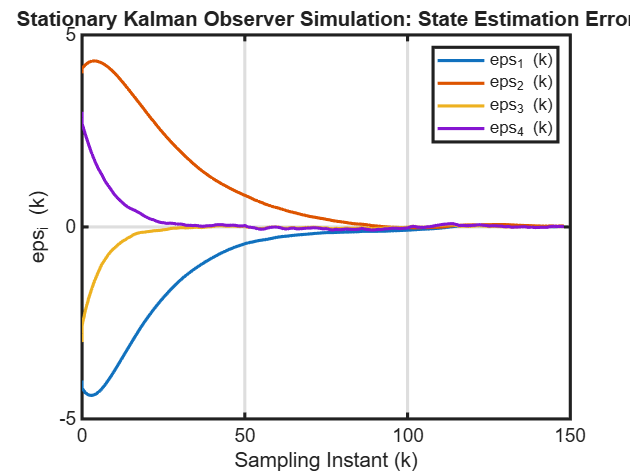

figure(5), plot(kT, est_err(1,:), kT, est_err(2,:), kT, est_err(3,:), kT, est_err(4,:)), grid
xlabel('Sampling Instant (k)'), ylabel('eps_i (k)')
legend('eps_1 (k)', 'eps_2 (k)', 'eps_3 (k)', 'eps_4 (k)'), 
title('Stationary Kalman Observer Simulation: State Estimation Error')

Observe the results of simulation. We can see that the estimation errors in the presence of state and measurement noises are becoming zero. 

**Task 4: **Now add the state and measurement noises in the simulation. Observe the results. The stationary Kalman Predictor is capable of estimating the states with a very small error, even in the presence of noises.

**Task 5:** You may change the estimation method to Kalman Filter. Do you observe any difference?

**Task 6: **Repeat the exercise for non minimum phase operating point

## Disturbance Estimation using Random Walk Model

Till now we have studied estimation of unmeasured states using a state estimator. Moreover, we assumed that the unmeasured disturbance signal, $d\left(k\right)\equiv w\left(k\right)$ where $w\left(k\right)$ represents a zero mean white noise signal. In practice, however, the disturbances can have time varying mean in addition to the random fluctuations. Can we develop an estimator to estimate such drifting unmeasured disturbances? In order to achieve this, we need to change the dynamic model and introduce artificial states that represent "dynamics" of unmeasured disturbances. This is achieved by assuming random walk of the form 

$d\left(k+1\right)=d\left(k\right)+w_d \left(k\right)$ ------(24)

where $w_d \left(k\right)$ is assumed to be a zero mean Gaussian signal with a diagonal covariance matrix 

$Q_d =\textrm{diag}\left\lbrack \begin{array}{cccc}
\sigma_1^2  & \sigma_2^2  & \ldotp \ldotp \ldotp \ldotp  & \sigma_d^2 
\end{array}\right\rbrack$  ------(25)

Here, $\sigma_i^2 :i=1,2,\ldotp \ldotp \ldotp ,d$ are treated as ***tuning parameters***. The dynamic model (24) is augmented with the linear state space model to arrive at the following augmented state space model 

$\left\lbrack \begin{array}{c}
x\left(k+1\right)\\
d\left(k+1\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
\Phi  & \Gamma_d \\
\left\lbrack 0\right\rbrack  & I
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\left(k\right)\\
d\left(k\right)
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
\Gamma \\
\left\lbrack 0\right\rbrack 
\end{array}\right\rbrack u\left(k\right)+\left\lbrack \begin{array}{c}
\left\lbrack 0\right\rbrack \\
I
\end{array}\right\rbrack w_d \left(k\right)$  ------(26)

$y\left(k\right)=\left\lbrack \begin{array}{cc}
C & \left\lbrack 0\right\rbrack 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\left(k\right)\\
d\left(k\right)
\end{array}\right\rbrack +v\left(k\right)$ ------(27)

Defining vectors and matrices 

$x_a \left(k\right)\equiv \left\lbrack \begin{array}{c}
x\left(k\right)\\
d\left(k\right)
\end{array}\right\rbrack \;,\;\;\Phi_a \equiv \left\lbrack \begin{array}{cc}
\Phi  & \Gamma_d \\
\left\lbrack 0\right\rbrack  & I
\end{array}\right\rbrack ,\;\;\Gamma_a \equiv \left\lbrack \begin{array}{c}
\Gamma \\
\left\lbrack 0\right\rbrack 
\end{array}\right\rbrack \;,\;\;\Gamma_{\textrm{da}} \equiv \left\lbrack \begin{array}{c}
\left\lbrack 0\right\rbrack \\
I
\end{array}\right\rbrack \;\textrm{abd}\;C_a =\left\lbrack \begin{array}{cc}
C & \left\lbrack 0\right\rbrack 
\end{array}\right\rbrack$    ------(28)

we get an augmented state space model  of the form 

 $\begin{array}{l}
x_a \left(\textrm{𝑘}+1\right)=\Phi_a x_a \left(\textrm{𝑘}\right)+\Gamma_a u\left(\textrm{𝑘}\right)+\Gamma_{\textrm{da}} \;w_d \left(\textrm{𝑘}\right)\\
y\left(\textrm{𝑘}\right)=C_a x\left(\textrm{𝑘}\right)+v\left(k\right)
\end{array}$ ------(29)

Using Hautus lemma, it can be shown that, if $\left(\Phi ,C\right)$ is an observable pair, then $\left(\Phi_a ,C_a \right)$ is also an observable pair provided the number of extra states do not exceed the number of measured outputs. When $\left(\Phi_a ,C_a \right)$ is observable, we can design a state estimator (Kalman or Luenberger observer) for the augmented system. The estimate of the augmented state generates estimate of the drifting disturbance along with the other unmeasured states. 

### Quadruple Tank Simulation 


clear all
close all

**Task 1: **On selecting the operating point, corresponding steady state linear discrete model and parameters will be loaded in the workspace. 

operating_pt=1;

% Load quadruple tank parameters and steady state The following file loads QTank data structre 
if operating_pt==1
load QTank_MinPhase_Model
else
 load QTank_NonMinPhase_Model 
end

phy= QTank.phy ;  
gam = QTank.gama_u ;
gam_d = QTank.gama_d ; 
C_mat = QTank.C_mat ; 

[n_st,n_ip] = size(gam);
[n_op, nx] = size(C_mat) ;
[nx, n_d] = size(gam_d)  ; 

phy_a = [ phy gam_d ; zeros(n_d,n_st) eye(n_d)]

phy_a =     0.9400         0    0.1431         0    0.0042
         0    0.9595         0    0.1027    0.0039
         0         0    0.8523         0    0.0528
         0         0         0    0.8952    0.0710
         0         0         0         0    1.0000


gam_a = [ gam ; zeros(n_d, n_ip)]

gam_a =     0.3229    0.0142
    0.0066    0.2461
         0    0.1769
    0.1182         0
         0         0


gam_d_a = [ zeros(n_st,n_d) ; eye(n_d)]

gam_d_a =      0
     0
     0
     0
     1


C_mat_a = [ C_mat zeros(n_op,n_d)]

C_mat_a =     0.5000         0         0         0         0
         0    0.5000         0         0         0


n_st_a = n_st + n_d ; % Dimension of the augmented phy matrix 
obsv_a = obsv( phy_a, C_mat_a )

obsv_a =     0.5000         0         0         0         0
         0    0.5000         0         0         0
    0.4700         0    0.0716         0    0.0021
         0    0.4797         0    0.0513    0.0020
    0.4418         0    0.1283         0    0.0079
         0    0.4603         0    0.0952    0.0075
    0.4153         0    0.1725         0    0.0165
         0    0.4416         0    0.1325    0.0161
    0.3903         0    0.2065         0    0.0274
         0    0.4237         0    0.1639    0.0272


rank(obsv_a)

ans = 5

samp_T = 4 ;  
QT_sys = ss(phy_a, [gam_a gam_d_a], C_mat_a, zeros(n_op,n_ip+n_d), QTank.samp_T ) ;

**Design Kalman / Luenberger predictor **

The state noise variance and measurement noise variance to be used in simulations are set as 0.01 and 0.0025 respectively

% Stationary Kalman filter predictor design 
v_sigma = 0.05 ;
R_mat = v_sigma^2*eye(n_op) ;
d_sigma = 0.1 ;
Q_mat = d_sigma^2*eye(n_d) ;

**Task 2: **Select the estimation method for simulating system with Luenberger Predictor, or Kalman Predictor. Set it to Kalman Predictor first

est_method = 2; 
if ( est_method == 1 )

Lp_mat_a =     1.0493    0.3368
    0.2665    1.2445
    0.8893    0.9079
    1.0669    1.9044
    2.2108    2.9412


** Task 3: **Tuning parameter for the augmented disturbance state       

      
    d_sigma_a=0.15;

rho_obs = 0.8500

    Q_mat_a = d_sigma_a^2*eye(n_d) ;

rho_phy = 1

    %  % Kalman predictor design
    [KEST,Lp_inf_a,P_inf_a] = kalman(QT_sys, Q_mat_a, R_mat, 0,"delayed")  ;
    Lp_mat_a = Lp_inf_a
else
    % Specify poles of the Luenberger observer error dynamics 
    p1=0.6;
    p2=0.8;
    p3=0.7;
    p4=0.55;
    p5=0.85;
    obs_poles = [ p1 p2 p3 p4 p5]'; % Error Dynamics Poles

    Lp_mat_a= place(phy_a', C_mat_a', obs_poles)  ;
    Lp_mat_a = Lp_mat_a'
end

 rho_obs = max(abs(eig(phy_a - Lp_mat_a * C_mat_a )))
rho_phy = max(abs(eig(phy_a))) 

**Task 3:** Simulate the observer dynamics. N is set to 500.

N = 500 ; % Simulation run time 

% Generate Input sequence 
uk1 = idinput(N,'rgs', [0,0.05]);
uk2 = idinput(N,'rgs', [0,0.05]);
uk = [ uk1' ; uk2'] ;

% Initialize matrices for saving 
xk = zeros(n_st, N) ;
yk = zeros(n_op,N) ;
xk(:,1) = [ 2 -2 1 -1]';
yk(:,1) = C_mat * xk(:,1) ;

xkahat = zeros(n_st_a, N) ;
ykhat = zeros(n_op,N) ;
ek = zeros(n_op,N) ;

% Generate state and measurement noise sequence 
vk = mvnrnd(zeros(n_op,1), R_mat, N) ;  % Generate measurement noise
vk = vk';
dk = mvnrnd(zeros(n_d,1), Q_mat , N) ;  % Generate state noise
dk = dk';

**Task 4: **Set the NO_Noise flag to **Switch OFF Noise** for simulating system under noise free conditions

NO_Noise =  1; % Set this flag for simulating system under noise free conditions 
if (NO_Noise)
    vk = 0 * vk ;  dk = 0 * dk ;  % Set state and measurement noise to zero 
end 

**Task 5: **Generate drifting mean for the disturbance input or set it to step input

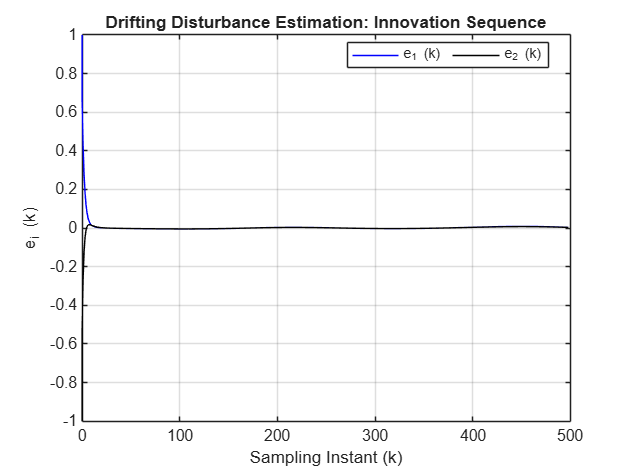

drift_dist_ON =  1 ;  % Setting this to 0 introduces sequence of step changes
if (drift_dist_ON)
    dk_mean = idinput(N,'rgs', [0,0.01]);
else

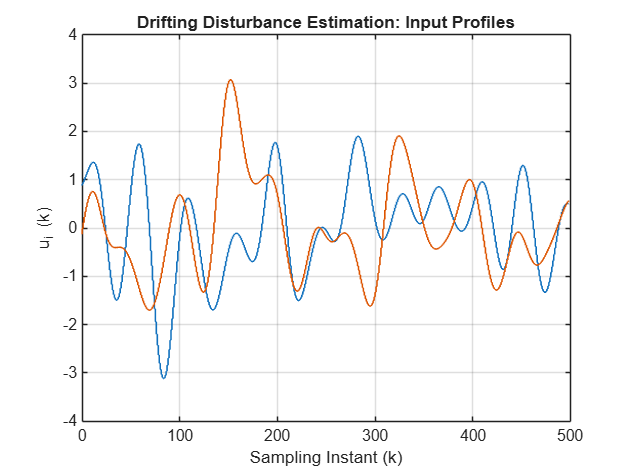

    dk_mean = idinput(N,'rbs', [0,0.025]);
end
dk_mean(1) = 0 ; 

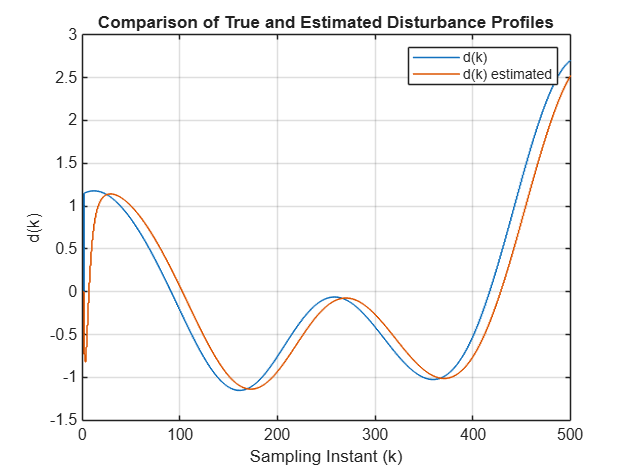

dk = dk + dk_mean' ; 

kT = zeros(N,1) ;
for k = 1 : N-1
    kT(k+1) = (k-1) ;

    % Simulate observer dynamics from k to k+1

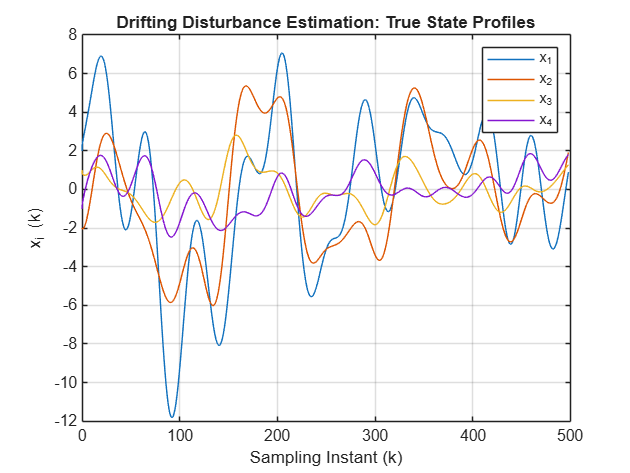


    % Stationary Kalman predictor
    ykhat(:,k) = C_mat_a * xkahat(:,k) ;
    ek(:,k) = yk(:,k) - ykhat(:,k) ;

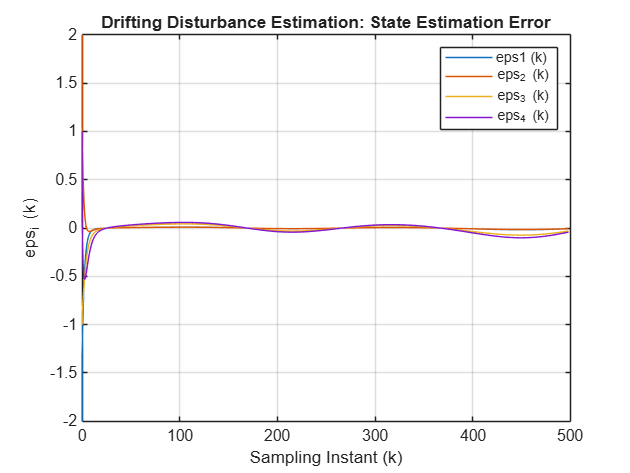

    xkahat(:,k+1)= phy_a * xkahat(:,k) + gam_a * uk(:,k) + Lp_mat_a * ek(:,k) ;

    ykhat(:,k+1) = C_mat_a * xkahat(:,k+1) ;


    % Simulate plant dynamics from k to k+1 
    xk(:,k+1)= phy * xk(:,k) + gam * uk(:,k) + gam_d * dk(:,k) ;
    yk(:,k+1) = C_mat * xk(:,k+1) + vk(:,k+1) ; 
end
ek(:,N) = ek(:,N-1) ;

est_err = xkahat(1:n_st,:) - xk ;  % State estimatin error

**Display Simulation Results**

figure(1), plot(kT, ek(1,:), 'b', kT, ek(2,:), 'k'), grid
xlabel('Sampling Instant (k)'), ylabel('e_i (k)')
legend('e_1 (k)', 'e_2 (k)', 'Orientation','horizontal','Location','Best')
title('Drifting Disturbance Estimation: Innovation Sequence')
figure(2), stairs(kT, uk', 'LineWidth',1), grid
xlabel('Sampling Instant (k)'), ylabel('u_i (k)'), 
title('Drifting Disturbance Estimation: Input Profiles')
figure(3), stairs(dk, 'LineWidth',1), grid
hold on
figure(3), stairs(xkahat(5,:), 'LineWidth',1)
hold off 
legend('d(k)', 'd(k) estimated')
xlabel('Sampling Instant (k)'), ylabel('d(k)'), 
title('Comparison of True and Estimated Disturbance Profiles')
figure(4), plot(kT, xk(1,:), kT, xk(2,:), kT, xk(3,:), kT, xk(4,:)), grid
xlabel('Sampling Instant (k)'), ylabel('x_i (k)')
legend('x_1', 'x_2', 'x_3', 'x_4'), 
title('Drifting Disturbance Estimation: True State Profiles')
figure(5), plot(kT, est_err(1,:), kT, est_err(2,:), kT, est_err(3,:), kT, est_err(4,:)), grid
xlabel('Sampling Instant (k)'), ylabel('eps_i (k)')
legend('eps1 (k)', 'eps_2 (k)', 'eps_3 (k)', 'eps_4 (k)'), 
title('Drifting Disturbance Estimation: State Estimation Error')

**Task 6: **Now add the state and measurement noises in the simulation. Observe the results. The stationary Kalman Filter is capable of estimating the states with a very small error, even in the presence of noises and the set disturbance input.

**Task 7:** You may change the estimation method to Luenberger Predictor. Do you observe any difference? See the variance of estimation error.

**Task 6: **Repeat the exercise for non minimum phase operating point.

It is evident from the simulation exercise that state augmentation is able to capture variation of the mean of the drifting disturbance with a delay. In the presence of state and measurement noise signals, these estimates can be noisy and choice of filter tuning parameters is a critical step in generating good performance. In the case of stationary Kalman filtering, reducing the random walk model variance results in smoother estimates but with larger estimation delay,

## Conclusion

In this lesson, we have studied stationary Kalman predictor and filter and their nominal stability characteristics. In addition, we have used the random walk model for estimating drifting unmeasured  disturbance signal.  Note that estimation of unmeasured disturbance can be used to develop a feed-forward controller that explicitly uses the disturbance estimate. Now we are ready to use these estimators for developing state feedback controllers. 

## References

Astrom, K. J. and B. Wittenmark, Computer Controlled Systems, Prentice Hall, 1990.

Franklin, G. F. and J. D. Powell, Digital Control of Dynamic Systems, Addison-Wesley, 1989.

Goodwin, G., Graebe, S. F., Salgado, M. E., Control System Design, PHI Learning, 2009.

Fadali, M. S. And Visioli, A., Digital Control Engineering: Analysis and Design, Academic Press, 2019. 